restoredefaultpath
addpath 'C:\Users\User\Cloud-Drive\BigFiles\libs\eeglab2023.0'
eeglab nogui;

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\User\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.7.9 to the path - new version 3.8.3 available
EEGLAB: adding "ICLabel" v? (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "MFFimport" v2.3 (see >> help eegplugin_mffimport)
EEGLAB: adding "clean_rawdata" v? (see >> help eegplugin_clean_rawdata) - new version 2.91 available
EEGLAB: adding "dipfit" v? (see >> help eegplugin_dipfit) - new version 5.3 available
EEGLAB: adding "firfilt" v? (see >> help eegplugin_firfilt) - new version 2.7.1 available


## Use of Anat's code to extract and preprocess orig data for Sleep Events (ss & kcomp) detection

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\User\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.7.9 to the path - new version 3.8.3 available
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel)
EEGLAB: adding "MFFimport" v2.3 (see >> help eegplugin_mffimport)
EEGLAB: adding "clean_rawdata" v2.8 (see >> help eegplugin_clean_rawdata) - new version 2.91 available
EEGLAB: adding "dipfit" v5.0 (see >> help eegplugin_dipfit) - new version 5.3 available
EEGLAB: adding "firfilt" v2.7.1 (see >> help eegplugin_firfilt)


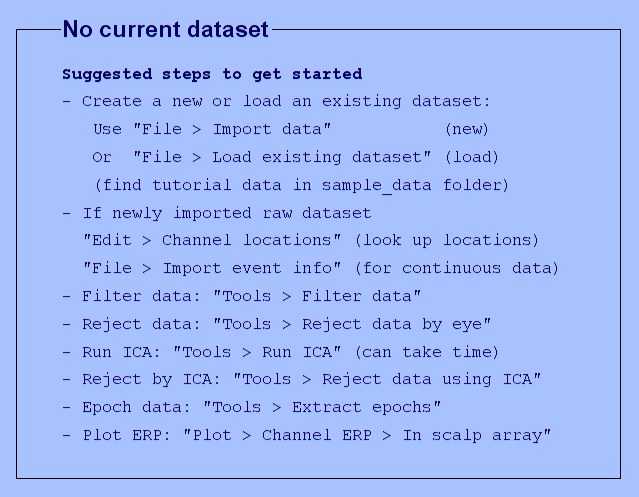

import_type ='eventDetectionChan';
preproc_name =  'imported';

input_dir = 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\';
output_dir = strcat('D:\AnatArziData\OExpOut\eventDetection\try2\',preproc_name,'_',import_type,'\no_filters\imported_scoringPrepro_mats\');

electrodesNames =     { 'E9','E22','E36','E104','E70','E83','E24','E124','E52','E92','Cz'}; 
electrodesEvenDetection_names = {'Fp1','Fp2','C3','C4','O1', 'O2','F3',  'F4', 'P3', 'P4', 'Cz'};
labelMapping = containers.Map(electrodesNames, electrodesEvenDetection_names);
subs = {'01','02','03','04','05','06','07','08','09','10','11','12','13','14','15','16','17','19','20','21','23','24','25','26','27','28','29','30','31','32','33','34','35','36','37','38'};
[ALLEEG EEG CURRENTSET ALLCOM] = eeglab;

if ~isfolder(output_dir)
    mkdir(output_dir);
end

for sub_ind=1:size(subs,2)
    for sleepFileNum=1:6
        % run only if output file doesnt exists
        sleep_files_name_suffix = strcat('_sleep',num2str(sleepFileNum),'_',preproc_name,'.set');
        output_filename = strcat('sub',subs(sub_ind),'_sleep',num2str(sleepFileNum),'_', preproc_name, '_',import_type);
        output_filename = output_filename{1};
        if isfile([output_dir output_filename '.set']) && isfile([output_dir output_filename '.mat']) && isfile([output_dir output_filename '.bdf'])
            string(strcat('Sub_',subs(sub_ind), ' already exists in path:',  output_filename))
            continue
        end
        
        % upload .set file
        set_filename = strcat('s_',subs(sub_ind),'_sleep',num2str(sleepFileNum),'_orig.set');
        set_filename = set_filename{1};
        if ~isfile([input_dir '\' set_filename])
            ['no input file ' input_dir set_filename]
            continue
        end
        try
            EEG =  pop_loadset(set_filename, input_dir);
            [ALLEEG, EEG, CURRENTSET] = eeg_store( ALLEEG, EEG, 0 );
            EEG = eeg_checkset(EEG);
        catch ME
            ['error uploading ' input_dir set_filename]
            continue
        end 

        % reref to mastoid
        EEG = rereferenceFullNightSleep(EEG,3); %3 = linked mastoid
            
        % get labels and change thire names 
        all_labels = {EEG.chanlocs.labels};
        electrodesNumber =[];
        for label_ind=1:size(all_labels,2)
            if any(ismember(electrodesNames, all_labels(label_ind)))
                electrodesNumber(end+1) = label_ind;
            end
        end
        if size(electrodesNames,2) > size(electrodesNumber,2) 
            'didnt find all electrodes labels' 
        end

        % exclude all electrode but the ones listed in loc
        chanexcl = 1:size(all_labels,2);
        chanexcl(electrodesNumber) = [];
        EEG = pop_select(EEG,'nochannel',chanexcl);

        % For EEG electrods
        lpfreq = 100;
        fprintf('Low-pass filtering above %dHz...\n',lpfreq);
        EEG = pop_eegfiltnew(EEG, [], lpfreq, 66, 0, [], 0);
        hpfreq = 0.2;% % (Anat's PSG was 0.5)
        fprintf('High-pass filtering EEG below %dHz...\n',hpfreq);
        EEG = pop_eegfiltnew(EEG, [], hpfreq, 8500, true, [], 0);

        % Update the labels
        EEG.chanlocs = arrayfun(@(x) setfield(x, 'labels', labelMapping(x.labels)), EEG.chanlocs);
        chansNames = {EEG.chanlocs.labels};

        %% savings
        % save .set
        [ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 1,'gui','off');
        
        EEG = pop_saveset(EEG, 'filename',[output_filename],'filepath',output_dir);

        % save .bdf
        pop_writeeeg(EEG, [output_dir output_filename '.bdf'],'TYPE','BDF'); %% no other intersting parameters.

        % save .mat
        subEvents = EEG.event;
        subData = EEG.data;
        samplefreq = EEG.srate;

        save([output_dir, output_filename '.mat'],"subEvents","subData","samplefreq",'chansNames');
    end
end

pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_01_sleep1_orig.set ...


Creating a new ALLEEG dataset 1


Referencing to E57E100.
Re-referencing data


Removing 116 channel(s)...


Low-pass filtering above 100Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 100 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 112.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 2.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.102941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 2


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-2.298371e+05 uV 
Warning SOPEN (EDF-Write): relative scaling error is 6.118463e-07 (due to roundoff in PhysMax/Min)
Warning SWRITE: 236 NaNs added to complete data block.


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_01_sleep2_orig.set ...


Creating a new ALLEEG dataset 3


Referencing to E57E100.
Re-referencing data


Removing 116 channel(s)...


Low-pass filtering above 100Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 100 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 112.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 2.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.102941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 4


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-1.829897e+04 uV 
Warning SOPEN (EDF-Write): relative scaling error is 1.601012e-06 (due to roundoff in PhysMax/Min)
Warning SWRITE: 16 NaNs added to complete data block.


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_01_sleep3_orig.set ...


Creating a new ALLEEG dataset 5


Referencing to E57E100.
Re-referencing data


Removing 116 channel(s)...


Low-pass filtering above 100Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 100 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 112.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 2.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.102941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 6


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-1.943514e+04 uV 
Warning SOPEN (EDF-Write): relative scaling error is 2.090286e-06 (due to roundoff in PhysMax/Min)
Warning SWRITE: 472 NaNs added to complete data block.


ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_01_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_01_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_01_sleep6_orig.set'

pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_02_sleep1_orig.set ...


Creating a new ALLEEG dataset 7


Referencing to E57E100.
Re-referencing data


Removing 116 channel(s)...


Low-pass filtering above 100Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 100 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 112.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 2.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.102941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 8


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-2.247681e+05 uV 
Warning SOPEN (EDF-Write): relative scaling error is 5.561287e-07 (due to roundoff in PhysMax/Min)
Warning SWRITE: 312 NaNs added to complete data block.


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_02_sleep2_orig.set ...


Creating a new ALLEEG dataset 9


Referencing to E57E100.
Re-referencing data


Removing 116 channel(s)...


Low-pass filtering above 100Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 100 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 112.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 2.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.102941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 10


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-1.464263e+04 uV 
Warning SOPEN (EDF-Write): relative scaling error is 2.107502e-06 (due to roundoff in PhysMax/Min)
Warning SWRITE: 220 NaNs added to complete data block.


ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_02_sleep3_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_02_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_02_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_02_sleep6_orig.set'

pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_03_sleep1_orig.set ...


Creating a new ALLEEG dataset 11


Referencing to E57E100.
Re-referencing data


Removing 116 channel(s)...


Low-pass filtering above 100Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 100 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 112.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 2.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.102941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 12


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-2.270998e+05 uV 
Warning SOPEN (EDF-Write): relative scaling error is 9.632330e-07 (due to roundoff in PhysMax/Min)
Warning SWRITE: 252 NaNs added to complete data block.


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_03_sleep2_orig.set ...


Creating a new ALLEEG dataset 13


Referencing to E57E100.
Re-referencing data


Removing 116 channel(s)...


Low-pass filtering above 100Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 100 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 112.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 2.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.102941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 14


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-1.509685e+04 uV 
Warning SOPEN (EDF-Write): relative scaling error is 3.273137e-06 (due to roundoff in PhysMax/Min)
Warning SWRITE: 480 NaNs added to complete data block.


ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_03_sleep3_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_03_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_03_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_03_sleep6_orig.set'

pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_04_sleep1_orig.set ...


Creating a new ALLEEG dataset 15


Referencing to E57E100.
Re-referencing data


Removing 116 channel(s)...


Low-pass filtering above 100Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 100 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 112.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 2.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.102941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 16


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-2.233327e+05 uV 
Warning SOPEN (EDF-Write): relative scaling error is 1.189369e-06 (due to roundoff in PhysMax/Min)
Warning SWRITE: 408 NaNs added to complete data block.


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_04_sleep2_orig.set ...


Creating a new ALLEEG dataset 17


Referencing to E57E100.
Re-referencing data


Removing 116 channel(s)...


Low-pass filtering above 100Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 100 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 112.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 2.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.102941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 18


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-1.580116e+04 uV 
Warning SOPEN (EDF-Write): relative scaling error is 2.768785e-06 (due to roundoff in PhysMax/Min)
Warning SWRITE: 52 NaNs added to complete data block.


ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_04_sleep3_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_04_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_04_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_04_sleep6_orig.set'

pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_05_sleep1_orig.set ...


Creating a new ALLEEG dataset 19


Referencing to E57E100.
Re-referencing data


Removing 116 channel(s)...


Low-pass filtering above 100Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 100 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 112.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 2.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.102941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 20


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-2.196882e+05 uV 
Warning SOPEN (EDF-Write): relative scaling error is 8.534824e-07 (due to roundoff in PhysMax/Min)
Warning SWRITE: 96 NaNs added to complete data block.


ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_05_sleep2_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_05_sleep3_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_05_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_05_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_05_sleep6_orig.set'

pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_06_sleep1_orig.set ...


Creating a new ALLEEG dataset 21


Referencing to E57E100.
Re-referencing data


Removing 116 channel(s)...


Low-pass filtering above 100Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 100 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 112.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 2.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.102941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 22


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-2.114519e+04 uV 
Warning SOPEN (EDF-Write): relative scaling error is 5.911511e-07 (due to roundoff in PhysMax/Min)
Warning SWRITE: 196 NaNs added to complete data block.


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_06_sleep2_orig.set ...


Creating a new ALLEEG dataset 23


Referencing to E57E100.
Re-referencing data


Removing 116 channel(s)...


Low-pass filtering above 100Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 100 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 112.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 2.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.102941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 24


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-1.982482e+04 uV 
Warning SOPEN (EDF-Write): relative scaling error is 8.275613e-07 (due to roundoff in PhysMax/Min)
Warning SWRITE: 228 NaNs added to complete data block.


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_06_sleep3_orig.set ...


Creating a new ALLEEG dataset 25


Referencing to E57E100.
Re-referencing data


Removing 116 channel(s)...


Low-pass filtering above 100Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 100 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 112.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 2.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.102941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 26


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-1.757081e+04 uV 
Warning SOPEN (EDF-Write): relative scaling error is 3.779351e-07 (due to roundoff in PhysMax/Min)
Warning SWRITE: 76 NaNs added to complete data block.


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_06_sleep4_orig.set ...


Creating a new ALLEEG dataset 27


Referencing to E57E100.
Re-referencing data


Removing 116 channel(s)...


Low-pass filtering above 100Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 100 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 112.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 2.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.102941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 28


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-2.207714e+04 uV 
Warning SOPEN (EDF-Write): relative scaling error is 1.751671e-06 (due to roundoff in PhysMax/Min)
Warning SWRITE: 468 NaNs added to complete data block.


ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_06_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_06_sleep6_orig.set'

pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_07_sleep1_orig.set ...


Creating a new ALLEEG dataset 29


Referencing to E57E100.
Re-referencing data


Removing 116 channel(s)...


Low-pass filtering above 100Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 100 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 112.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 2.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.102941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 30


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-3.011200e+04 uV 
Warning SOPEN (EDF-Write): relative scaling error is 6.486202e-08 (due to roundoff in PhysMax/Min)
Warning SWRITE: 68 NaNs added to complete data block.


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_07_sleep2_orig.set ...


Creating a new ALLEEG dataset 31


Referencing to E57E100.
Re-referencing data


Removing 116 channel(s)...


Low-pass filtering above 100Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 100 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 112.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 2.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.102941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 32


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-3.427809e+04 uV 
Warning SOPEN (EDF-Write): relative scaling error is 2.962898e-07 (due to roundoff in PhysMax/Min)
Warning SWRITE: 284 NaNs added to complete data block.


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_07_sleep3_orig.set ...


Creating a new ALLEEG dataset 33


Referencing to E57E100.
Re-referencing data


Removing 116 channel(s)...


Low-pass filtering above 100Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 100 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 112.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 2.000000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.102941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 34


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-2.981205e+04 uV 
Warning SOPEN (EDF-Write): relative scaling error is 1.650968e-06 (due to roundoff in PhysMax/Min)
Warning SWRITE: 344 NaNs added to complete data block.


ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_07_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_07_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_07_sleep6_orig.set'

ans = "Sub_08 already exists in path:sub08_sleep1_imported_eventDetectionChan"

ans = "Sub_08 already exists in path:sub08_sleep2_imported_eventDetectionChan"

ans = "Sub_08 already exists in path:sub08_sleep3_imported_eventDetectionChan"

ans = "Sub_08 already exists in path:sub08_sleep4_imported_eventDetectionChan"

ans = "Sub_08 already exists in path:sub08_sleep5_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_08_sleep6_orig.set'

ans = "Sub_09 already exists in path:sub09_sleep1_imported_eventDetectionChan"

ans = "Sub_09 already exists in path:sub09_sleep2_imported_eventDetectionChan"

ans = "Sub_09 already exists in path:sub09_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_09_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_09_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_09_sleep6_orig.set'

ans = "Sub_10 already exists in path:sub10_sleep1_imported_eventDetectionChan"

ans = "Sub_10 already exists in path:sub10_sleep2_imported_eventDetectionChan"

ans = "Sub_10 already exists in path:sub10_sleep3_imported_eventDetectionChan"

ans = "Sub_10 already exists in path:sub10_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_10_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_10_sleep6_orig.set'

ans = "Sub_11 already exists in path:sub11_sleep1_imported_eventDetectionChan"

ans = "Sub_11 already exists in path:sub11_sleep2_imported_eventDetectionChan"

ans = "Sub_11 already exists in path:sub11_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_11_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_11_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_11_sleep6_orig.set'

ans = "Sub_12 already exists in path:sub12_sleep1_imported_eventDetectionChan"

ans = "Sub_12 already exists in path:sub12_sleep2_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_12_sleep3_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_12_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_12_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_12_sleep6_orig.set'

ans = "Sub_13 already exists in path:sub13_sleep1_imported_eventDetectionChan"

ans = "Sub_13 already exists in path:sub13_sleep2_imported_eventDetectionChan"

ans = "Sub_13 already exists in path:sub13_sleep3_imported_eventDetectionChan"

ans = "Sub_13 already exists in path:sub13_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_13_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_13_sleep6_orig.set'

ans = "Sub_14 already exists in path:sub14_sleep1_imported_eventDetectionChan"

ans = "Sub_14 already exists in path:sub14_sleep2_imported_eventDetectionChan"

ans = "Sub_14 already exists in path:sub14_sleep3_imported_eventDetectionChan"

ans = "Sub_14 already exists in path:sub14_sleep4_imported_eventDetectionChan"

ans = "Sub_14 already exists in path:sub14_sleep5_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_14_sleep6_orig.set'

ans = "Sub_15 already exists in path:sub15_sleep1_imported_eventDetectionChan"

ans = "Sub_15 already exists in path:sub15_sleep2_imported_eventDetectionChan"

ans = "Sub_15 already exists in path:sub15_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_15_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_15_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_15_sleep6_orig.set'

ans = "Sub_16 already exists in path:sub16_sleep1_imported_eventDetectionChan"

ans = "Sub_16 already exists in path:sub16_sleep2_imported_eventDetectionChan"

ans = "Sub_16 already exists in path:sub16_sleep3_imported_eventDetectionChan"

ans = "Sub_16 already exists in path:sub16_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_16_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_16_sleep6_orig.set'

ans = "Sub_17 already exists in path:sub17_sleep1_imported_eventDetectionChan"

ans = "Sub_17 already exists in path:sub17_sleep2_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_17_sleep3_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_17_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_17_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_17_sleep6_orig.set'

ans = "Sub_19 already exists in path:sub19_sleep1_imported_eventDetectionChan"

ans = "Sub_19 already exists in path:sub19_sleep2_imported_eventDetectionChan"

ans = "Sub_19 already exists in path:sub19_sleep3_imported_eventDetectionChan"

ans = "Sub_19 already exists in path:sub19_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_19_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_19_sleep6_orig.set'

ans = "Sub_20 already exists in path:sub20_sleep1_imported_eventDetectionChan"

ans = "Sub_20 already exists in path:sub20_sleep2_imported_eventDetectionChan"

ans = "Sub_20 already exists in path:sub20_sleep3_imported_eventDetectionChan"

ans = "Sub_20 already exists in path:sub20_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_20_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_20_sleep6_orig.set'

ans = "Sub_21 already exists in path:sub21_sleep1_imported_eventDetectionChan"

ans = "Sub_21 already exists in path:sub21_sleep2_imported_eventDetectionChan"

ans = "Sub_21 already exists in path:sub21_sleep3_imported_eventDetectionChan"

ans = "Sub_21 already exists in path:sub21_sleep4_imported_eventDetectionChan"

ans = "Sub_21 already exists in path:sub21_sleep5_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_21_sleep6_orig.set'

ans = "Sub_23 already exists in path:sub23_sleep1_imported_eventDetectionChan"

ans = "Sub_23 already exists in path:sub23_sleep2_imported_eventDetectionChan"

ans = "Sub_23 already exists in path:sub23_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_23_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_23_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_23_sleep6_orig.set'

ans = "Sub_24 already exists in path:sub24_sleep1_imported_eventDetectionChan"

ans = "Sub_24 already exists in path:sub24_sleep2_imported_eventDetectionChan"

ans = "Sub_24 already exists in path:sub24_sleep3_imported_eventDetectionChan"

ans = "Sub_24 already exists in path:sub24_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_24_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_24_sleep6_orig.set'

ans = "Sub_25 already exists in path:sub25_sleep1_imported_eventDetectionChan"

ans = "Sub_25 already exists in path:sub25_sleep2_imported_eventDetectionChan"

ans = "Sub_25 already exists in path:sub25_sleep3_imported_eventDetectionChan"

ans = "Sub_25 already exists in path:sub25_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_25_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_25_sleep6_orig.set'

ans = "Sub_26 already exists in path:sub26_sleep1_imported_eventDetectionChan"

ans = "Sub_26 already exists in path:sub26_sleep2_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_26_sleep3_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_26_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_26_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_26_sleep6_orig.set'

ans = "Sub_27 already exists in path:sub27_sleep1_imported_eventDetectionChan"

ans = "Sub_27 already exists in path:sub27_sleep2_imported_eventDetectionChan"

ans = "Sub_27 already exists in path:sub27_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_27_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_27_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_27_sleep6_orig.set'

ans = "Sub_28 already exists in path:sub28_sleep1_imported_eventDetectionChan"

ans = "Sub_28 already exists in path:sub28_sleep2_imported_eventDetectionChan"

ans = "Sub_28 already exists in path:sub28_sleep3_imported_eventDetectionChan"

ans = "Sub_28 already exists in path:sub28_sleep4_imported_eventDetectionChan"

ans = "Sub_28 already exists in path:sub28_sleep5_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_28_sleep6_orig.set'

ans = "Sub_29 already exists in path:sub29_sleep1_imported_eventDetectionChan"

ans = "Sub_29 already exists in path:sub29_sleep2_imported_eventDetectionChan"

ans = "Sub_29 already exists in path:sub29_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_29_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_29_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_29_sleep6_orig.set'

ans = "Sub_30 already exists in path:sub30_sleep1_imported_eventDetectionChan"

ans = "Sub_30 already exists in path:sub30_sleep2_imported_eventDetectionChan"

ans = "Sub_30 already exists in path:sub30_sleep3_imported_eventDetectionChan"

ans = "Sub_30 already exists in path:sub30_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_30_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_30_sleep6_orig.set'

ans = "Sub_31 already exists in path:sub31_sleep1_imported_eventDetectionChan"

ans = "Sub_31 already exists in path:sub31_sleep2_imported_eventDetectionChan"

ans = "Sub_31 already exists in path:sub31_sleep3_imported_eventDetectionChan"

ans = "Sub_31 already exists in path:sub31_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_31_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_31_sleep6_orig.set'

ans = "Sub_32 already exists in path:sub32_sleep1_imported_eventDetectionChan"

ans = "Sub_32 already exists in path:sub32_sleep2_imported_eventDetectionChan"

ans = "Sub_32 already exists in path:sub32_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_32_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_32_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_32_sleep6_orig.set'

ans = "Sub_33 already exists in path:sub33_sleep1_imported_eventDetectionChan"

ans = "Sub_33 already exists in path:sub33_sleep2_imported_eventDetectionChan"

ans = "Sub_33 already exists in path:sub33_sleep3_imported_eventDetectionChan"

ans = "Sub_33 already exists in path:sub33_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_33_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_33_sleep6_orig.set'

ans = "Sub_34 already exists in path:sub34_sleep1_imported_eventDetectionChan"

ans = "Sub_34 already exists in path:sub34_sleep2_imported_eventDetectionChan"

ans = "Sub_34 already exists in path:sub34_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_34_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_34_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_34_sleep6_orig.set'

ans = "Sub_35 already exists in path:sub35_sleep1_imported_eventDetectionChan"

ans = "Sub_35 already exists in path:sub35_sleep2_imported_eventDetectionChan"

ans = "Sub_35 already exists in path:sub35_sleep3_imported_eventDetectionChan"

ans = "Sub_35 already exists in path:sub35_sleep4_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_35_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_35_sleep6_orig.set'

ans = "Sub_36 already exists in path:sub36_sleep1_imported_eventDetectionChan"

ans = "Sub_36 already exists in path:sub36_sleep2_imported_eventDetectionChan"

ans = "Sub_36 already exists in path:sub36_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_36_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_36_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_36_sleep6_orig.set'

ans = "Sub_37 already exists in path:sub37_sleep1_imported_eventDetectionChan"

ans = "Sub_37 already exists in path:sub37_sleep2_imported_eventDetectionChan"

ans = "Sub_37 already exists in path:sub37_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_37_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_37_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_37_sleep6_orig.set'

ans = "Sub_38 already exists in path:sub38_sleep1_imported_eventDetectionChan"

ans = "Sub_38 already exists in path:sub38_sleep2_imported_eventDetectionChan"

ans = "Sub_38 already exists in path:sub38_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_38_sleep4_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_38_sleep5_orig.set'

ans = 'no input file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_38_sleep6_orig.set'